# Deep Learning - COVID-19.

Actualmente, el COVID-19 es una de las mayores preocupaciones para la sociedad, por lo que se ha convertido en una prioridad para muchos campos de investigación. En relación con el diagnostico de este virus y las infecciones pulmonares que produce, una de las pruebas utilizadas para extraer evidencias clinicas en su deteccion es el denominado TAC (Tomografía Axial Computarizada). El TAC pulmonar permite ver si la afección ha llegado al pulmón. Se buscan zonas aparentes visibles como "nubes".

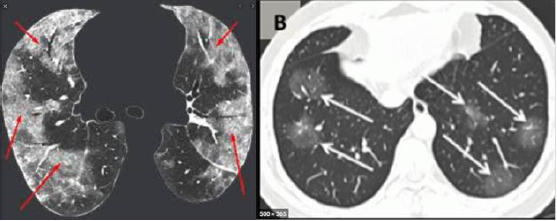

La aplicación de técnicas de aprendizaje profundo en investigación médica, cuando el diagnóstico se hace a través de imagen y hay grandes volúmenes de información disponible, es uno de los campos con más auge en la actualidad. Por ello, a partir de un conjunto de imagenes, se desarrolla una red neuronal convolucional (CNN), que permita la clasificacion de las imagenes entre positivas o negaticas en COVID-19. Y se evalua los resultados para evaluar la arquitectura.

## Carga y Exploración de las Imágenes.

En primero lugar se carga las imagenes en el espacio de trabajo, para ello se crea un fichero .zip con las carpetas con las diferentes imagenes. Se extrae y se cargan en un almacen de datos de imagen 'imds', es una forma alternativa y más rapida para trabajar con imagenes mediante su dirección de memoria. Además etiqueta automaticamente las imágenes en función de los nombres de las carpetas.

unzip('CT_COVID19.zip');

imds = imageDatastore('CT_COVID19', ...
    'IncludeSubfolders',true,'LabelSource','foldernames');

Otro metodo alternativo, es indicar acceder a los datos a través de la dirección de memoria, pero este metodo no es portable, debido a que depende de la ubicación de las carpetas.

Se muestra pantalla algunas de las imagenes de forma aleatoria, para observar a que tipo de imagenes se va a hacer frente.

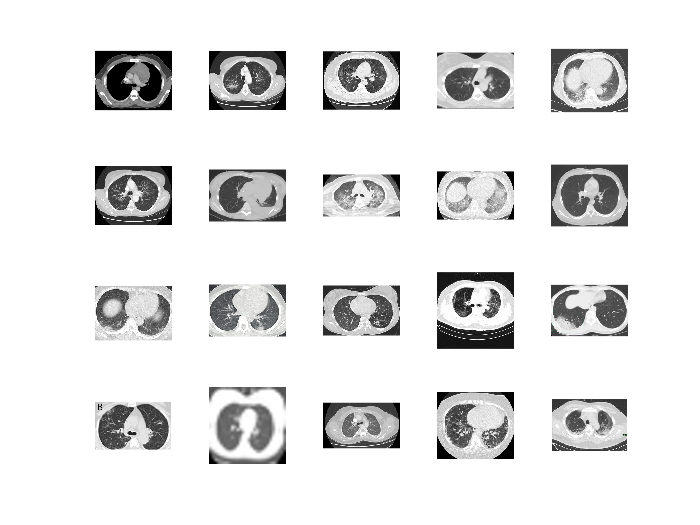

figure;
perm = randperm(746,20);
for i = 1:20
    subplot(4,5,i);
    imshow(imds.Files{perm(i)});
end

Se calcula el numero de imágenes en cada categoria y se almacena en una tabla, donde en este caso solo se tiene dos categorias, cuando es positivo (349 imágenes) y negativo (397 imágenes).

labelCount=countEachLabel(imds)

labelCount = 2×2 table
       Label       Count
    ___________    _____

    CT_COVID        349 
    CT_NonCOVID     397 


## Preprocesado de las Imágenes.

Como se puede observar al representar diferentes imagenes se observa que presentan diferentes tamaños y diferentes canales, por lo que se realiza un preprocesado.

Se lee cada imagen y se evalua cuantos canales tiene, si este es mayor a 1, se pasa a un canal ya que se va a trabajar con imagenes en escala de grises. Posteriormente se redimensiona la imagen a un tamaño fijo (fixedSize), que será el de entrada a la red neuronal y por ultimo se sobreescribe la nueva imagen.

fixedSize=[28 28];

for i=1:1:746
    imag=imread(imds.Files{i});
    if (size(imag,3)>1)
        imag=rgb2gray(imag);
    end
    imag=imresize(imag, fixedSize);
    imwrite(imag,imds.Files{i});
end

## Tamaño de los Conjunto de Entrenamiento y Validación.

Se divide los datos según su función, si son para entrenar el modelo o para realizar la validación. 

Se define un 80% de datos para entreno, los cuales se seleccionan de forma aleatoria y se dividen en dos conjuntos diferentes.

numTrainFiles=0.8;
[imdsTrain,imdsValidation] = splitEachLabel(imds,numTrainFiles,'randomize');

## Definición de la Arquitectura de la Red.

Se define la arquitectura de la red neuronal convolucional.

layers = [
    imageInputLayer([fixedSize 1])
    
    convolution2dLayer(3,8,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,16,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    fullyConnectedLayer(2)
    softmaxLayer
    classificationLayer];

La arquitectura de la red se divide principalmente en dos, en la función de aprendizaje y clasificacion.

### Función de aprendizaje.

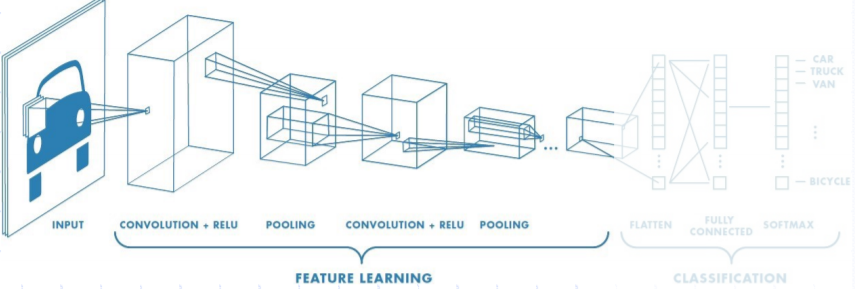

En la función de aprendizaje se extraen y aprenden las características a través de convoluciones, se introducen elementos no lineales a través de las activaciones para adaptarse mejor a los datos y se reduce la dimensionalidad y preserva la constancia en cuanto a la localización espacial con el pooling.

Se especifica el tamaño de las imagenes (imageInputLayer), la cual será del mismo orden que fixedSize de un canal. 

La capa convolucional (convolution2dLayer), el primer argumento es el tamaño del filtro, que es la altura y la anchura de los filtros, que es 3, por lo que el tamaño del filtro es 3x3, el segundo parametro es el numero de filtros, que es el número de neuronas que se conectan a la misma región de entrada, su valor varia conforme se avanza en la red, 8-16-32.

 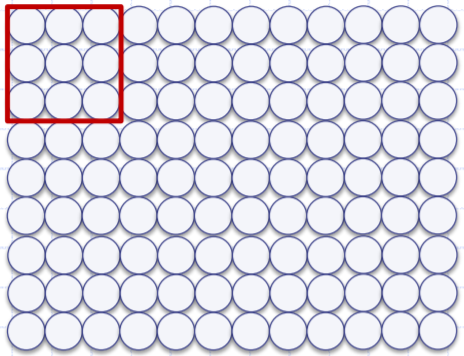

Además se indica que rellene el mapa de entidades de entrada, 'Padding', y con igual 'same' se garantiza que el tamaño de salida sea el mismo que el tamaño de entrada, realizando lo que se conoce como un Padding ligero.

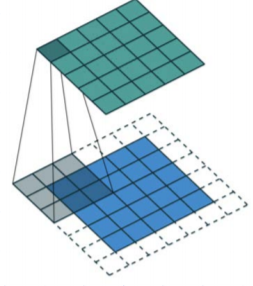

La capa de normalización por lotes (batchNormalizationLayer) normaliza las activaciones y gradientes que se propagan a través de una red, lo que hace que la capacitación en red sea un problema de optimización más fácil. Se usa capas ReLU (reluLayer) que son capas de normalización por lotes entre capas convolucionales y no lineales, para acelerar el entrenamiento de la red y reducir la sensibilidad a la inicialización de la red, reemplazando los valores negartivos por 0s y dejando igual los positivos. El procedimiento es crear la capa de normalización y posteriormente la capa ReLU.

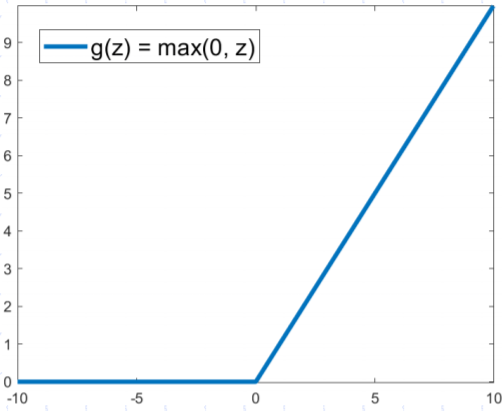

La capa de agrupación máxima (maxPooling2dLayer) muestrea las capas, reduciendo el tamaño del mapa de características y elimina información redundante. Dicho muestreo permite aumentar el número de filtros en capas convolucionales más profundas. La capa de agrupación máxima devuelve los valores máximos de las regiones rectangulares de las entradas, especificadas por el primer argumentos, poolSize. En este caso la región rectangular es [2,2], y el argumento 'Stride' especifica el tamaño del paso que toma la función mientras escanea a lo largo de la entrada.

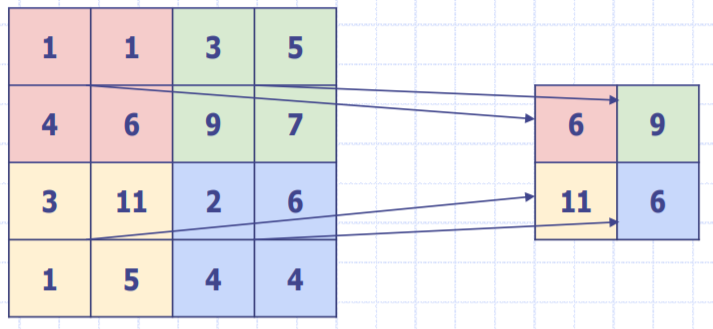

### Clasificación.

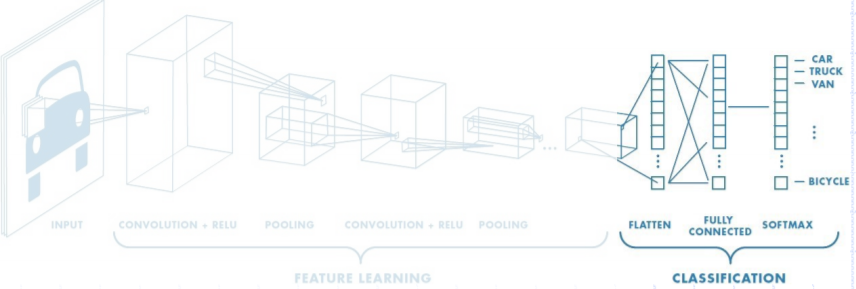

La capa totalmente conectada (fullyConnectedLayer) es una capa que todas las neuronas se conectan a todas las neuronas de la capa anterior, combinando todas las caracteristicas aprendidas por las capas anteriores para identificar los patrones más grandes. La ultima capa combina todas las características, por lo que se indica el numero de clases en la función.

La capa softmax (softmaxLayer) normaliza la salida de la ultima capa, el cual consiste en numeros positivos que suman uno, que luego se usan como probabilidades de clasificación de cada capa. 

La capa de clasificación (classificationLayer) es la etapa final, donde en esta capa utiliza las probabilidades de softmax y asigna la entrada una de las clases y calcula la perdida.

## Especificación de las Opciones de Entrenamiento

Una vez definida la arquitectura de la red, se definen las opciones de entrenamiento, donde se ajustará los valores de la tasa de aprendizaje y las épocas.

La tasa de aprendizaje, si este valor es muy pequeño la convergencia es lenta y puede quedar atascado en minimos locales, pero si es muy grande, el proceso se vuelve inestable y es posible que diverja, por lo que se prueban los valores de 0,001, 0,005 y 0,01, el cúal se seleccionará con el que mejor resultados se obtengan, que en este caso es para 0,01.

Las épocas, se define una época muy grande para ver el comportamiento de la red, teniendo cuidado con el sobreajuste y selecciona el punto antes de que se produzca,pero el resultado que se obtiene es que a partir de la interacción 100 se  empieza a estabilizar la red, aunque las perdidas en la validación aumenta muy poco, por lo que se definen 35 epocas, para que de tiempo a estabilizarse la red al entrenarla y las perdidas de validacion no aumente, aunque su comportamiento es constante.

Los demás valores indican la división entren cada época, la entrada de los datos de validación y su frecuencia.

options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.01, ...
    'MaxEpochs',35, ...
    'Shuffle','every-epoch', ...
    'ValidationData',imdsValidation, ...
    'ValidationFrequency',30, ...
    'Verbose',false, ...
    'Plots','training-progress');

## Entrenamiento de la Red.

Se entrena la red con los datos de entrenamiento, definiendo en la funcion la arquitectura de la red y las opciones de entreno. Donde se desplegará una ventana,  que muestrará el proceso de entrenamiento y los resultados finales.

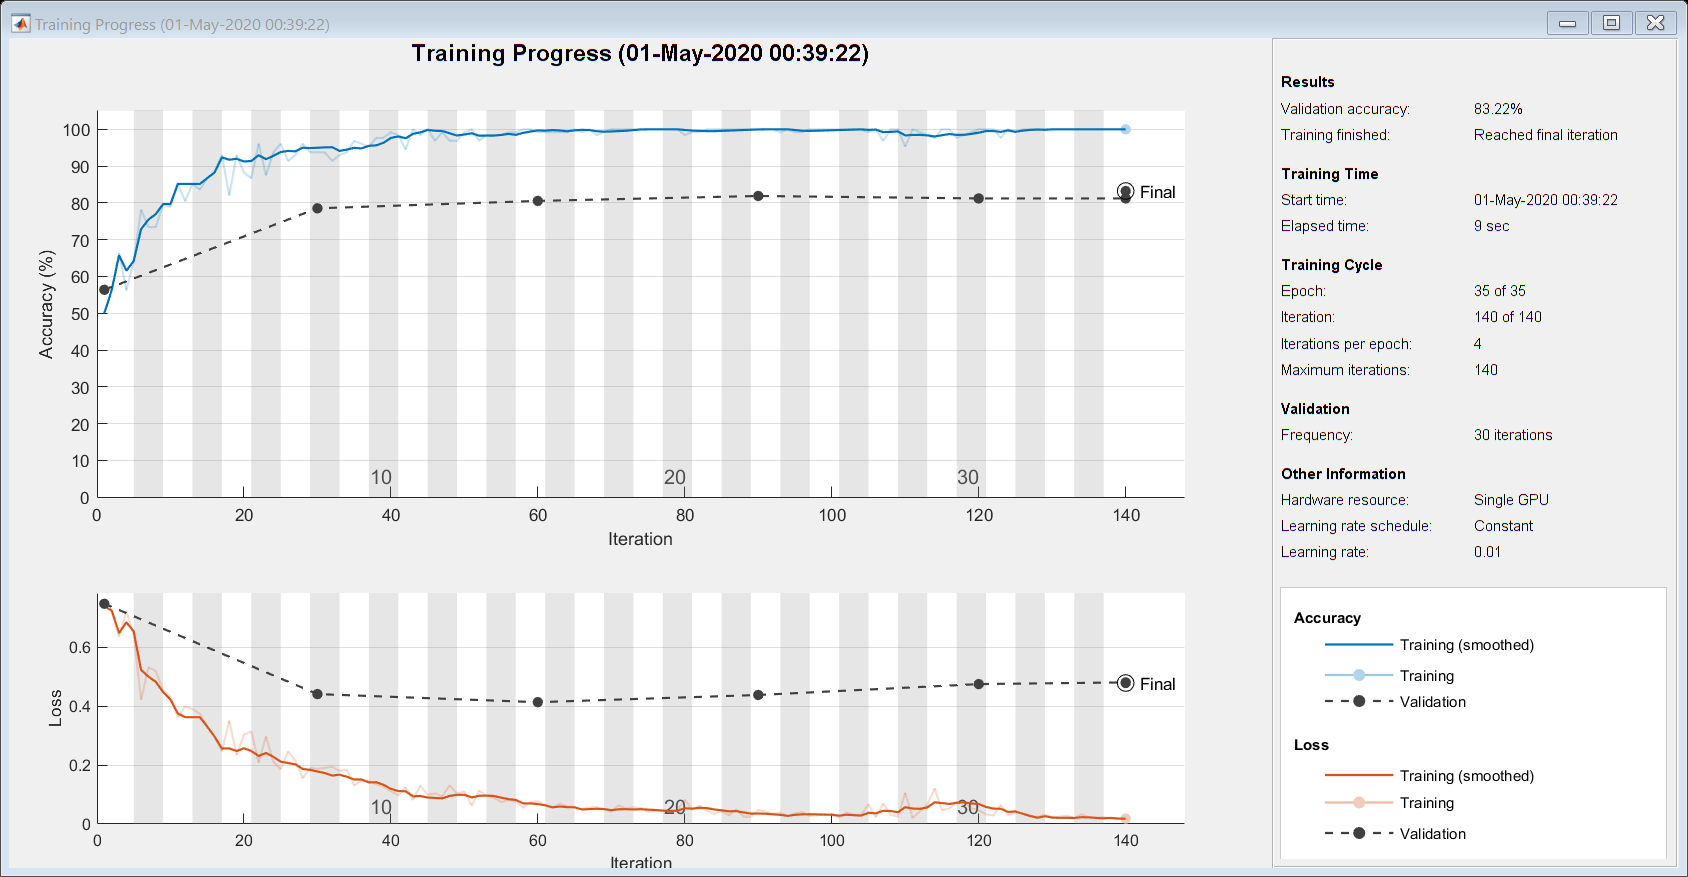

net = trainNetwork(imdsTrain,layers,options);

Si se presta atención a la gráfica de las perdidas, se observá que las épocas se definen antes que las perdidas de la validación aumente, es decir, se produzca el sobreajuste.

## Clasificación de las Imágenes de Validación y Resultados.

Se predice las etiquetas de los datos de validación utilizando la red y se calcula la matriz de confusión, que gracias a ella se podrá obtener diferentes parametros para valorar la red neuronal. 

YPred = classify(net,imdsValidation);
YValidation = imdsValidation.Labels;


CM=confusionmat(YPred,YValidation);

Sensitivity=CM(1,1)/(CM(1,1)+CM(2,1))

Sensitivity = 0.8000

Specificity=CM(2,2)/(CM(1,2)+CM(2,2))

Specificity = 0.8608

Accuracy=(CM(1,1)+CM(2,2))/(CM(1,1)+CM(1,2)+CM(2,1)+CM(2,2))

Accuracy = 0.8322

Precision=CM(1,1)/(CM(1,1)+CM(1,2))

Precision = 0.8358

F1Score=2*(Precision*Sensitivity)/(Precision+Sensitivity)

F1Score = 0.8175

## Fichero CSV

Se crea un fichero de texto en formato CSV con las métricas de evaluación.

filename='CT_COVID19v1.txt';
fileID=fopen(filename,'w');
fprintf(fileID,"Sensitivity,Specificity,Accuracy,Precision,F1 Score");
fprintf(fileID,"\n%f,%f,%f,%f,%f",Sensitivity,Specificity,Accuracy,Precision,F1Score);
fclose(fileID);

## Conclusión

La precisión de los datos de validación suele estar en valores en torno al 82%, consiguiendo una red muy valida para detectar el Covid-19.